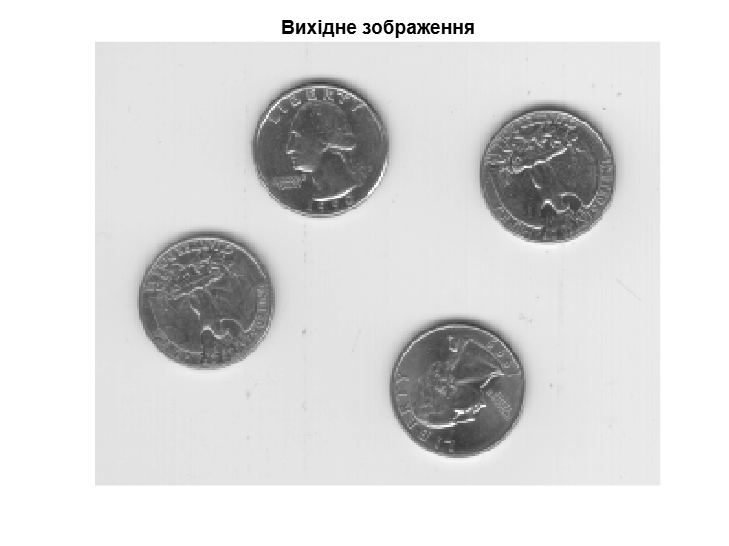

% 1. Завантажте з бібліотеки MATLAB кілька різних зображень.

f = imread('eight.tif');
figure; imshow(f); title('Вихідне зображення');

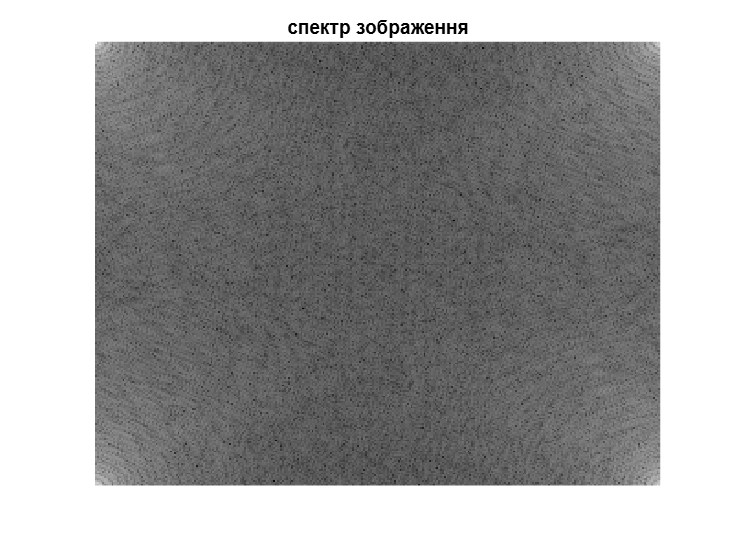

% 2. З використанням функції F = fft2(f) сформуйте й відобразіть
% двовимірні спектри зображень. При відображенні спектра використовуйте або
% логарифмічний масштаб, або підберіть масштаб уручну шляхом ділення
% значень спектра на деяку константу. Можна, також, пронормувати значення
% спектра до максимального, а потім домножити кожне значення на 255
% (максимальна яскравість для uint8).

F = fft2(f);
S = abs(F);
Slog = log(1 + S);

figure;
imshow(Slog, []); title('спектр зображення');

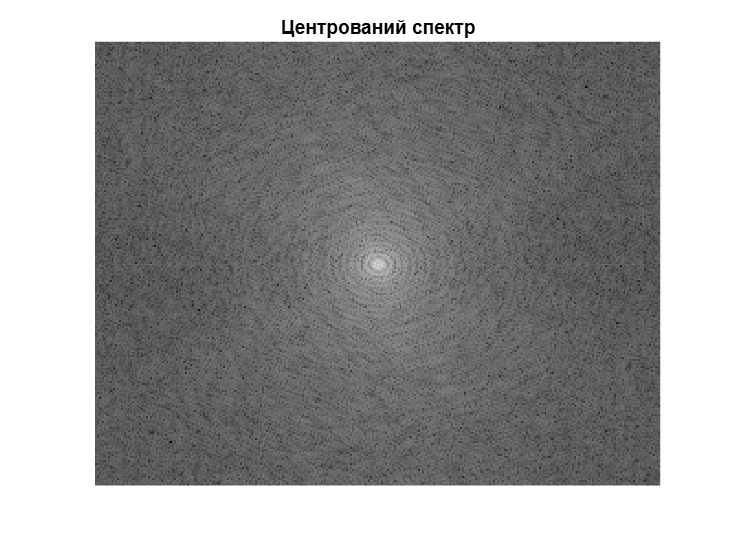

% 3. З використанням функції fftshift приведіть нульову частоту в спектрі до центру вікна відображення.
Fc = fftshift(F);
Sclog = log(1 + abs(Fc));
figure; imshow(Sclog, []); title('Центрований спектр');

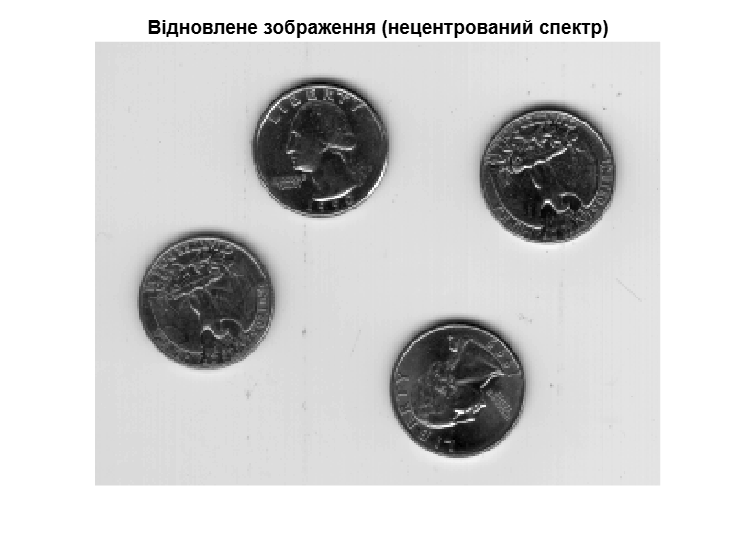

% 4. З використанням функції ifft2(F) відновіть зображення за його спектром 
% (використовуйте спектри з нульовою частотою у верхньому лівому куті й з нульовою частотою в центрі вікна).
% Поясніть отримані в обох випадках результати.

f_rec1 = ifft2(F);
figure; imshow(abs(f_rec1), []); title('Відновлене зображення (нецентрований спектр)');

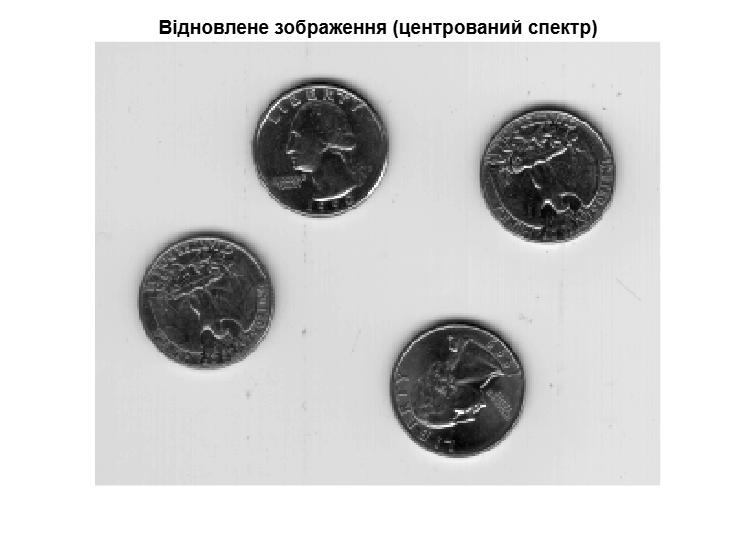

Fdc = ifftshift(Fc);
f_rec2 = ifft2(Fdc);
figure; imshow(abs(f_rec2), []); title('Відновлене зображення (центрований спектр)');

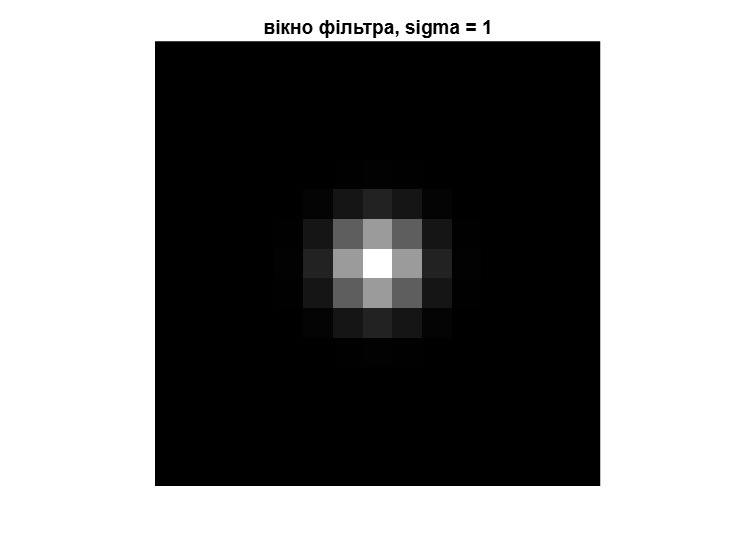

% 5. З використанням функції fspecial('gaussian') задайте двовимірний
% фільтр із параметрами [M N], sigma в області просторових змінних.
% Відобразіть у вигляді зображення вигляд вікна цього фільтра.

M = 15; N = 15; sigma = 1;
h = fspecial('gaussian', [M N], sigma);

figure; imshow(h, []); title(['вікно фільтра, sigma = ', num2str(sigma)]);

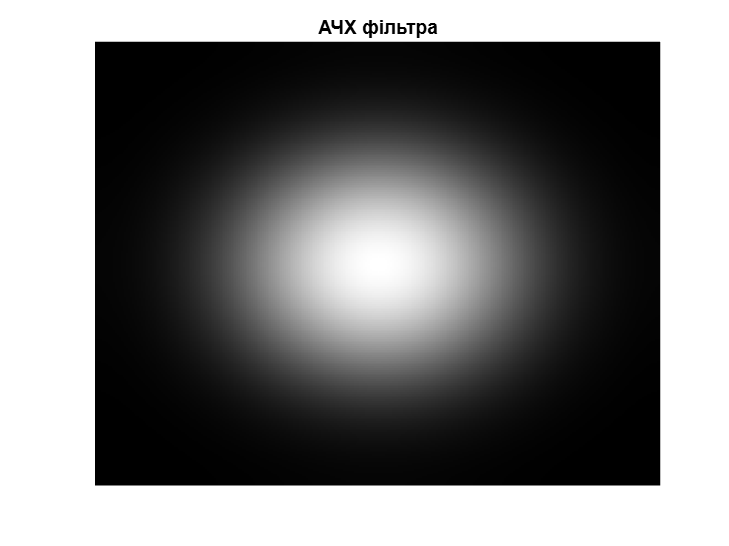

% 6. Визначте вигляд частотної характеристики даного фільтра. Відобразіть
% АЧХ двовимірного фільтра у вигляді зображення – imshow.

H = fft2(h, size(f,1), size(f,2));
H_shifted = fftshift(H);
figure; imshow(log(1 + abs(H_shifted)), []); title('АЧХ фільтра');

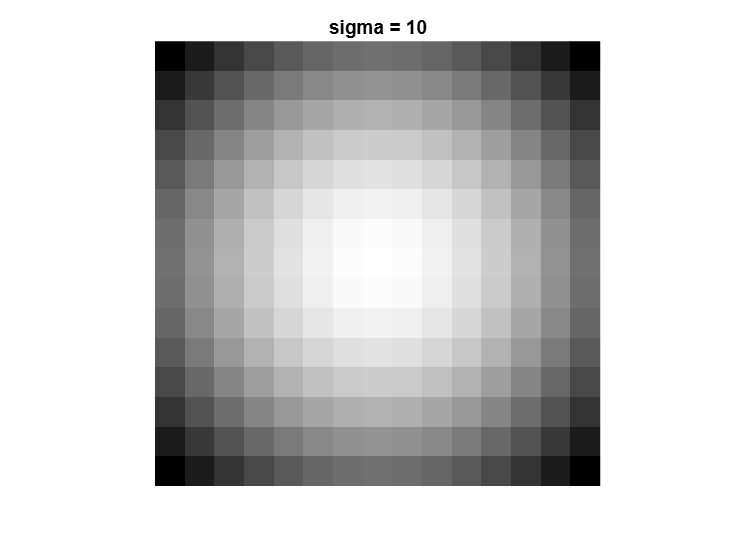

% 7. Змініть параметр sigma фільтра, і повторіть п.п. 5,6. Поясніть
% відмінності в отриманих результатах.

sigma2 = 10;
h2 = fspecial('gaussian', [M N], sigma2);

figure; imshow(h2, []); title(['sigma = ', num2str(sigma2)]);

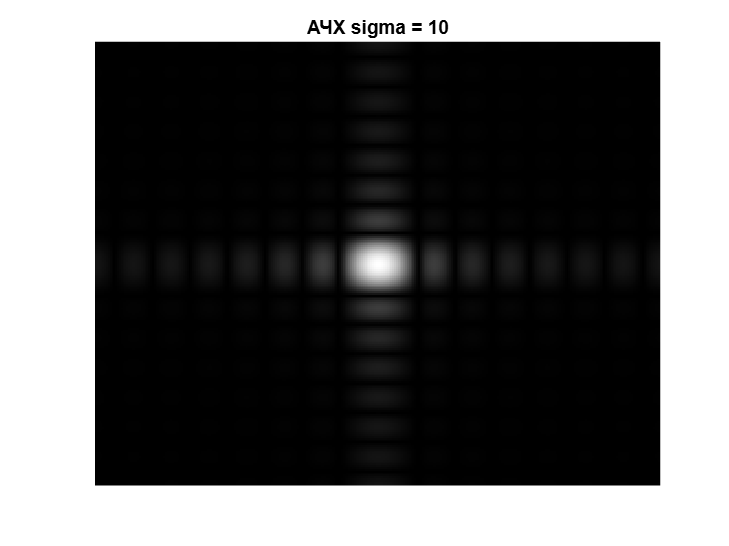

H2 = fft2(h2, size(f,1), size(f,2));
H2_shifted = fftshift(H2);
figure; imshow(log(1 + abs(H2_shifted)), []); title('АЧХ sigma = 10');

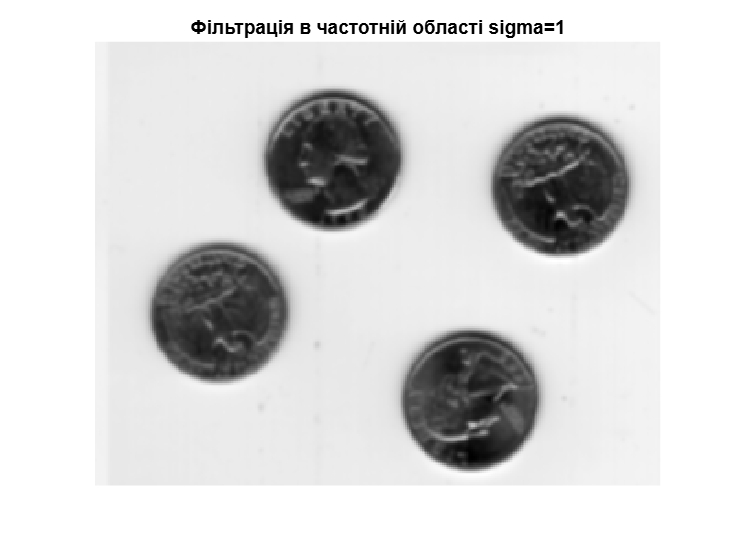

% 8. Виконайте фільтрацію зображень у частотній області з використанням
% фільтрів згідно п.п. 5, 6, 7. Поясніть відмінності в отриманих результатах.

F_filtered1 = F .* H;
f_filtered1 = ifft2(F_filtered1);
figure; imshow(abs(f_filtered1), []); title('Фільтрація в частотній області sigma=1');

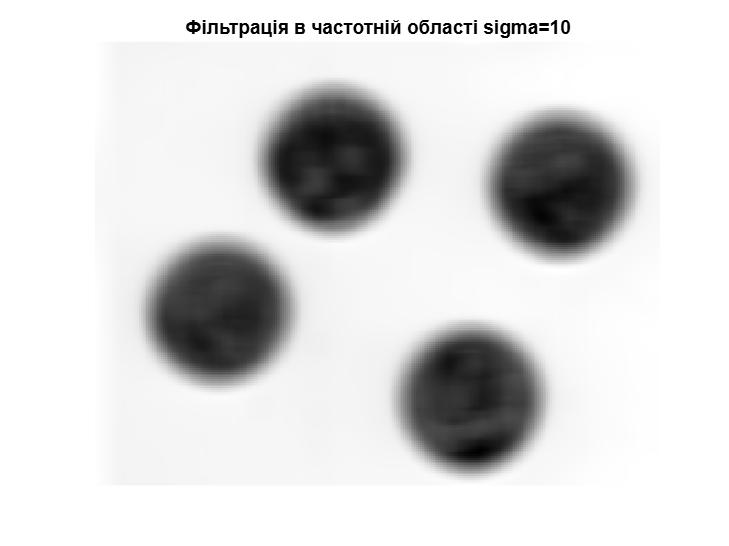

F_filtered2 = F .* H2;
f_filtered2 = ifft2(F_filtered2);
figure; imshow(abs(f_filtered2), []); title('Фільтрація в частотній області sigma=10');

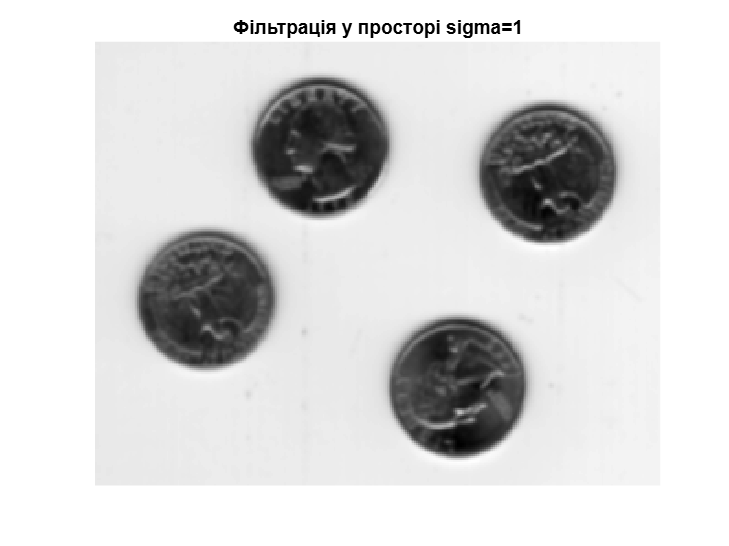

f_spatial1 = imfilter(f, h, 'replicate');
figure; imshow(f_spatial1, []); title('Фільтрація у просторі sigma=1');

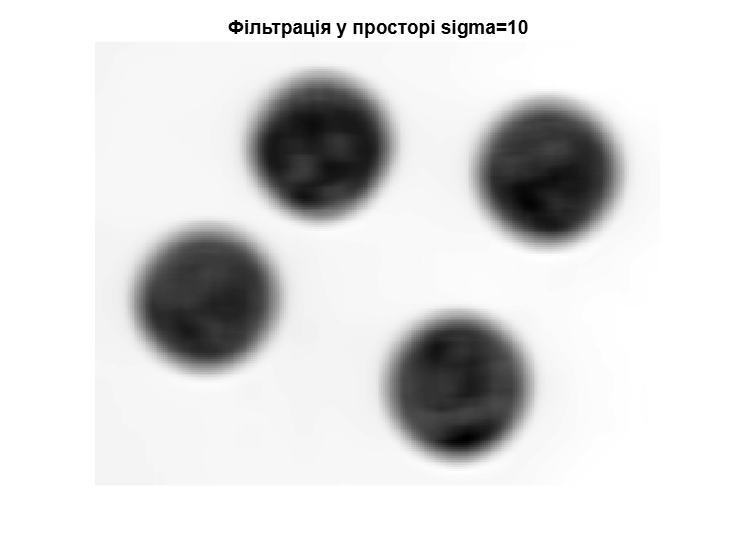


f_spatial2 = imfilter(f, h2, 'replicate');
figure; imshow(f_spatial2, []); title('Фільтрація у просторі sigma=10');